initCobraToolbox(false)



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2023
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.38.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
Original LP has 1 row, 2 columns, 1 non-zero
Objective value = 0
OPTIMAL SOLUTION FOUND BY LP PRESOLVER

 > [glpk] Primal optimality condition in solveCobraLP satisfied.Could not find installation of mosek, so it cannot be tested

 > [matlab] Primal optimality condition in solveCobraLP satisfied.
   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago 

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

					Support           LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    1 	    1 	    1 	    1 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek        	active        	    0 	    - 	    0 	    - 	    - 	    0
	

#### sp. 7942 FBA

Import the model first

modelpath = [pwd filesep 'model' filesep 'iJN678'];
algae_core = readCbModel([modelpath,'.xml']);

One subSystem per reaction, so each model.subSystems{x} is a character array.


If want to search the information about the reaction by metabolites, reactions or other names, use this.

surfNet(Synechococcus_sp7942,"sucr")

Add a new reaction, which transport sucrose into extracellular space.

model = algae_core;
R = 'h[p] + sucr[p] <=> h[c] + sucr[c]';
mblist = {'h[p]','h[c]','sucr[c]','sucr[p]'};

model = addMetabolite(model,'sucr[p]','metName','Sucrose C12H22O11','metFormula','C12H22O11','Charge',0);

Error using addMultipleMetabolites
The following Metabolite ID(s) are already present in the model:
sucr[p]

Error in addMetabolite (line 131)
newmodel = addMultipleMetabolites(model,metID,multiArgs{:});


model = addReaction(model,'SUCRt2','reactionName','Sucrose transport in via proton symport', ...
    'metaboliteList',mblist, ...
    'subSystem','S_Transport__Extracellular', ...
    'stoichCoeffList',[-1;1;-1;1], ...
    'lowerBound',0);


modelNew = changeObjective(model, 'BIOMASS__1');

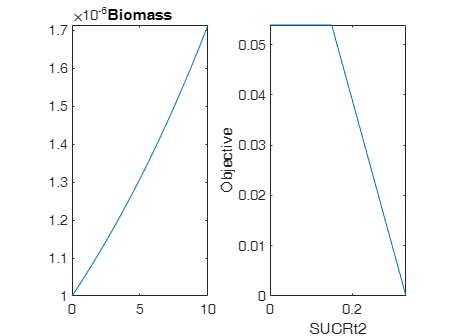

%printRxnFormula(modelNew)

[controlFlux, objFlux] = robustnessAnalysis(model_test,...
'SUCRt2',250,false,'BIOMASS__1','max');

Robustness analysis in progress ...
100%    [........................................]


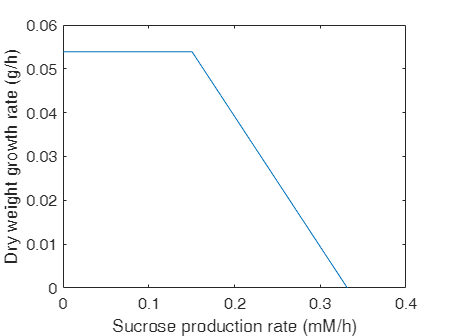


close all;
figure
plot(controlFlux,objFlux)
xlabel('Sucrose production rate (mM/h)')
ylabel('Dry weight growth rate (g/h)')

model_test = algae_core;
%model_test = addReaction(model_test,'SPP','geneRule','');
%model_test = addReaction(model_test,'SPS','geneRule','');
mblist = {'h[e]','h[c]','sucr[e]','sucr[c]'};
model_test = addMetabolite(model_test,'sucr[e]','metName','Sucrose C12H22O11','metFormula','C12H22O11','Charge',0);

Error using addMultipleMetabolites
The following Metabolite ID(s) are already present in the model:
sucr[e]

Error in addMetabolite (line 131)
newmodel = addMultipleMetabolites(model,metID,multiArgs{:});

model_test = addExchangeRxn(model_test,'sucr[e]',0,1000);
model_test = addReaction(model_test,'SUCRt2','reactionName','Sucrose transport in via proton symport', ...
    'metaboliteList',mblist, ...
    'subSystem','S_Transport__Extracellular', ...
    'stoichCoeffList',[1;-1;1;-1], ...
    'lowerBound',-1000);
model_test = addReaction(model_test,'EX_nh4_e','lowerBound',-1000);
model_test = addReaction(model_test,'EX_mg2_e','lowerBound',-1000);

surfNet(model_test,'EX_nh4_e')
%model_test = addSinkReactions(model_test,'sucr[p]',0,1000);
model_test = changeObjective(model_test,'BIOMASS__1',1);

sol = optimizeCbModel(model_test);
printFluxVector(model_test,sol.x,true,true) % only prints nonzero rows



ans = 60

Step number	Biomass
Dynamic FBA analysis in progress ...
100%    [........................................]


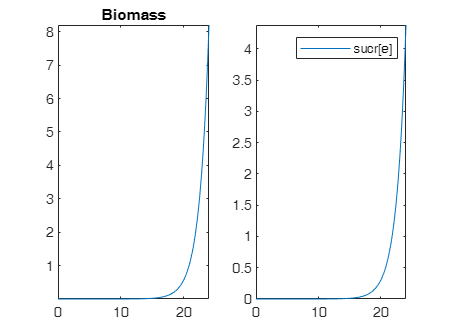

% Synechococcus_sp7942 = changeObjective(Synechococcus_sp7942,{'EX_sucr[e]','BIOMASS__1'},2);
% exchange reaction for substrate in environment

smc = [0]; % Glucose, Acetate concentration (all in mM)

Xec = 1e-6; % initial biomass
dt = 1.0/10.0; % time steps
time = 24.0/dt; % simulation time

plot_rxn = {'EX_sucr[e]'};

[concentrationMatrix, excRxnNames, timeVec,...
    biomassVec] = dynamicFBA(Synechococcus_sp7942,  plot_rxn, smc, Xec, dt, time, plot_rxn); 

[GeneClasses RxnClasses modelIrrevFM]=pFBA(Synechococcus_sp7942, 'geneoption', 0, 'skipclass', 1);

nonZeroFlag = 1;
printFluxVector(modelIrrevFM, modelIrrevFM.lb,true,true)

%parsed = parseCD('aaa.xml');
disp(Synechococcus_sp7942.rxns(findExcRxns(Synechococcus_sp7942)))

    {'EX_gln__L_e'   }
    {'EX_hco3_e'     }
    {'EX_mn2_e'      }
    {'EX_arg__L_e'   }
    {'SK_for_c'      }
    {'EX_mg2_e'      }
    {'EX_ptrc_e'     }
    {'DM_h2_c'       }
    {'EX_ca2_e'      }
    {'EX_nh4_e'      }
    {'DM_dialurate_c'}
    {'DM_co_c'       }
    {'EX_fe2_e'      }
    {'EX_cu2_e'      }
    {'DM_5drib_c'    }
    {'SK_amylose_c'  }
    {'EX_k_e'        }
    {'SK_14glucan_c' }
    {'SK_glycogen_c' }
    {'EX_h2o_e'      }
    {'EX_o2_e'       }
    {'EX_co2_e'      }
    {'EX_leu__L_e'   }
    {'EX_cobalt2_e'  }
    {'EX_no3_e'      }
    {'EX_zn2_e'      }
    {'EX_fe3_e'      }
    {'EX_so4_e'      }
    {'EX_spmd_e'     }
    {'EX_mobd_e'     }
    {'EX_ni2_e'      }
    {'EX_na1_e'      }
    {'EX_cynt_e'     }
    {'EX_h_e'        }
    {'EX_photon410_e'}
    {'EX_photon430_e'}
    {'EX_photon450_e'}
    {'EX_photon470_e'}
    {'EX_photon490_e'}
    {'EX_photon510_e'}
    {'DM_amob_c'     }
    {'EX_photon530_e'}
    {'EX_photon550_e'}
    {'EX_ph

sol_test = optimizeCbModel(Synechococcus_sp7942);

surfNet(Synechococcus_sp7942,"BIOMASS__1", 0,sucr_sol2.x,1,1);

% Synechococcus_sp7942 = addReaction(Synechococcus_sp7942,'EX_sucr_e','metaboliteList',{'sucr[e]'},'stoichCoeffList',[-1],'upperBound',1000);

surfNet(Synechococcus_sp7942,'EX_')

'EX_' is not a metabolite, reaction or gene of the model.
Searching for related objects:

  id    Rxn             LB / UB, rxnNames, grRules, matches
 #430           EX_k_e  -0.046 / 1000, K+ exchange, , rxnBiGGID:EX_k_e, rxns:EX_k_e
      k[e]   <=> 
 #475           EX_h_e  -100 / 1000, H+ exchange, , rxnBiGGID:EX_h_e, rxns:EX_h_e
      h[e]   <=> 
 #439          EX_o2_e  -100 / 1000, O2 exchange, , rxnBiGGID:EX_o2_e, rxns:EX_o2_e
      o2[e]   <=> 
 #601          EX_pi

% NOTICE: I modify the model2JSON.m, remove the line 213
%fprintf(fid,strcat('"sbo":"',model.geneSBOTerms{i},'"\n'));
%writeCbModel(model_test,'format','json','filename','aa.json');


%model_core = addReaction(model_core,'EX_photon_e','lowerBound',-1000,'upperBound',1000);
sol = optimizeCbModel(algae_core);
% printFluxVector(model_test,sol.x,true,true) % only prints nonzero rows

%surfNet(model, 'f6p[c]', 0,sol.x,1,1)